# Using the oiCompute function

This script illustrates how the scene spectral radiance is transformed by the optics to the sensor irradiance. The key function is **oiCompute**.

We use the term optical image (oi) to refer to the object that describes the basic properties of the spectral irradiance at the sensor. The conversion of the scene radiance to spectral radiance is largely determined by the parameters of the **optics**. The optics object is attached to the oi object.

The oiCompute function governs the computation from scene to the oi. For a longer discussion see t_oiIntroduction.

See also: 

    t_oiIntroduction, t_sceneIntroduction, s_optics<TAB>

ieInit

## Create a scene and oi (irradiance) image from an array of points

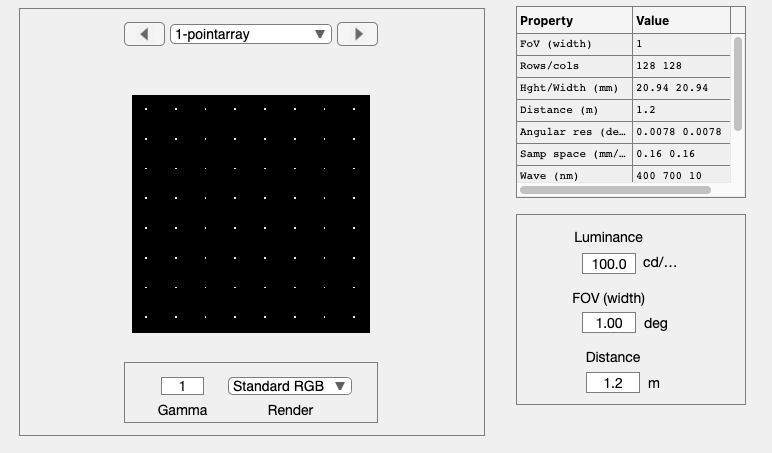

scene = sceneCreate('point array');
scene = sceneSet(scene,'hfov',1);
sceneWindow(scene);

## Diffraction limited optics

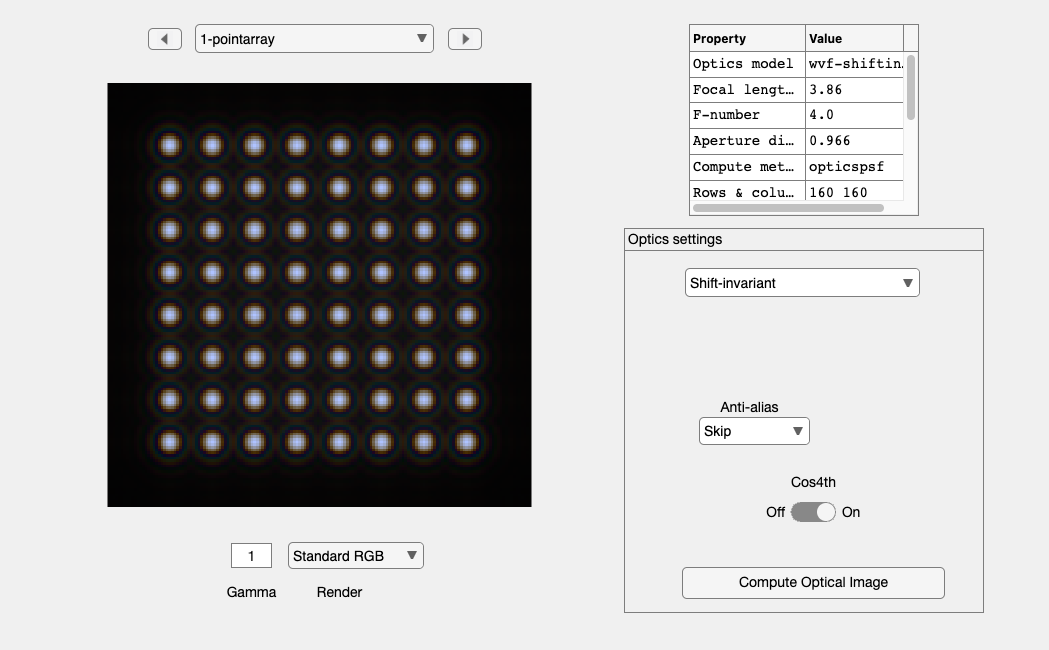

oi = oiCreate('wvf');

% Compute optical image and show it
oi = oiCompute(oi,scene);
oiWindow(oi);

## Increase the f-number, compute and show the new image

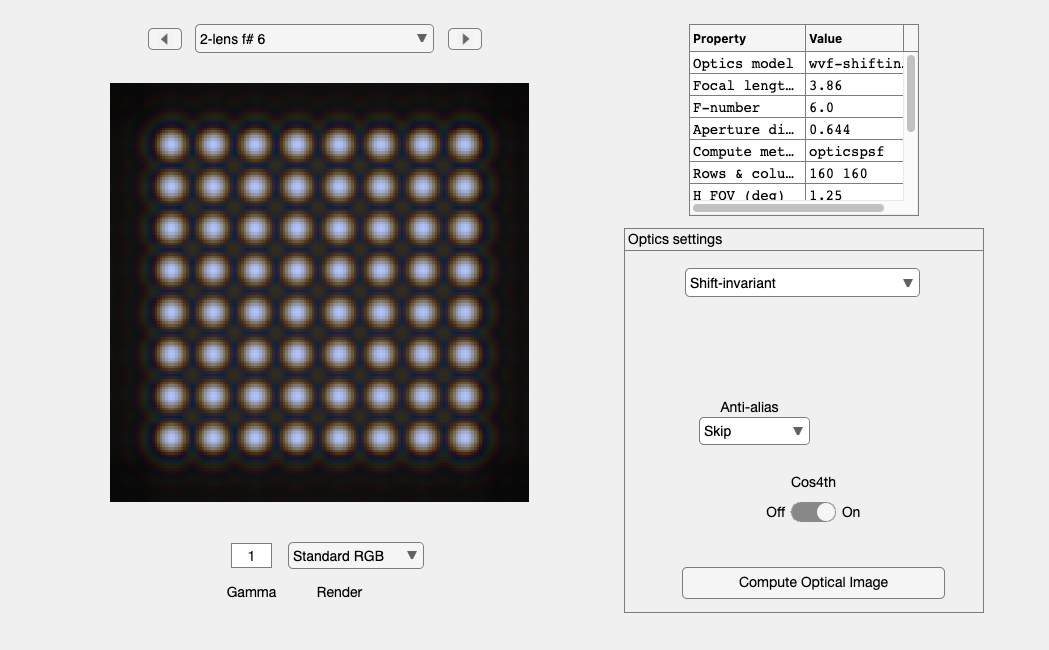

fnSmall = oiGet(oi,'optics fnumber');
fnBig   = 1.5 * fnSmall;
oi2 = oiSet(oi,'optics fnumber',fnBig);
oi2 = oiCompute(oi2,scene);
oi2 = oiSet(oi2,'name',sprintf('lens f# %.0f\n',fnBig));
oiWindow(oi2);

## Plot the psf of the optics

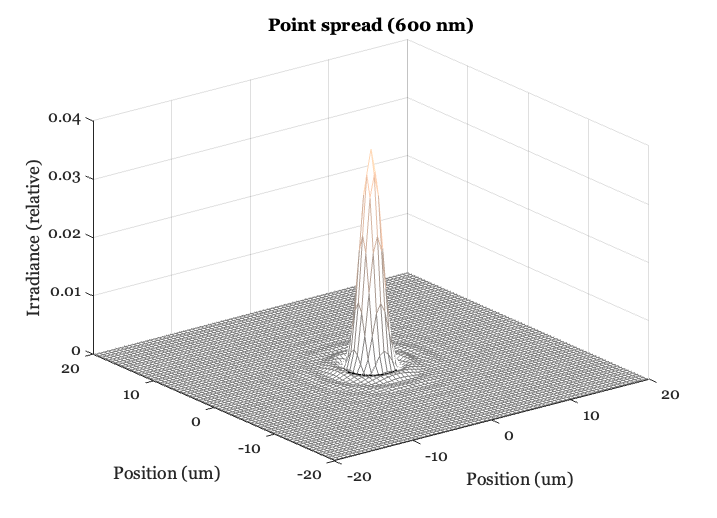

thisWave = 600;
oiPlot(oi,'psf',[],thisWave);
set(gca,'xlim',[-20 20],'ylim',[-20 20]);
colormap(0.5*copper(64) + 0.5*ones(size(copper(64))));

## Plot the irradiance image

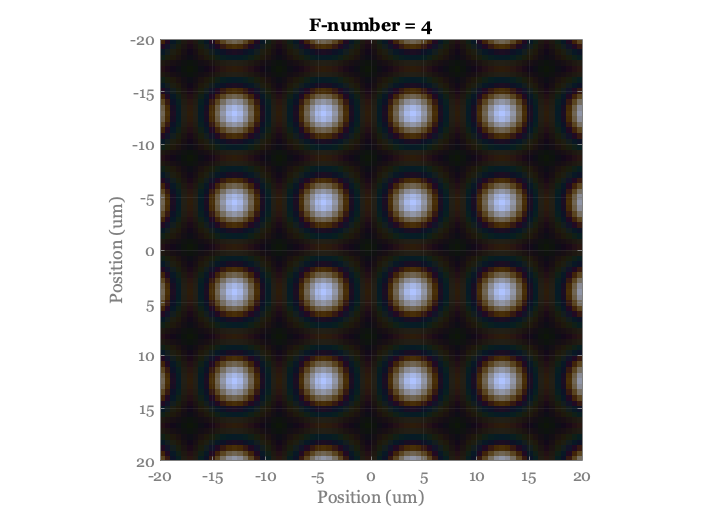

gridSpacing = 5; % um
oiPlot(oi,'irradiance image with grid',[],gridSpacing);
set(gca,'xlim',[-20 20],'ylim',[-20 20])
title(sprintf('F-number = %.0f',fnSmall))

## Change the f/# of the optics and replot

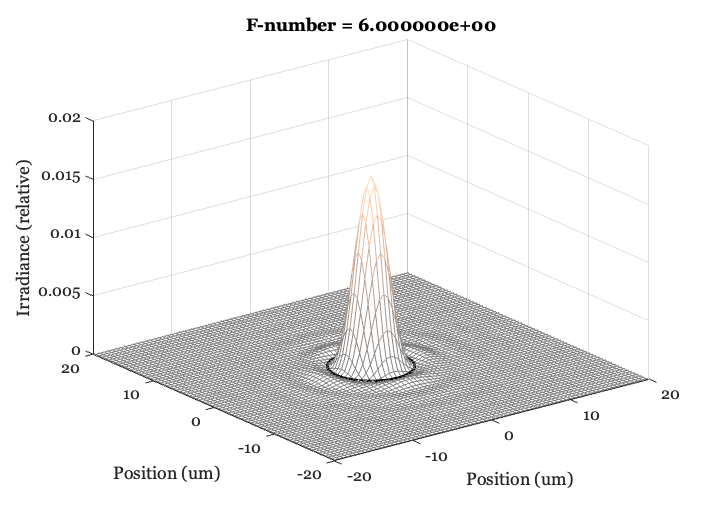

oiPlot(oi2,'psf',[],thisWave);
set(gca,'xlim',[-20 20],'ylim',[-20 20])

colormap(0.5*copper(64) + 0.5*ones(size(copper(64))))
title(sprintf('F-number = %d',fnBig))

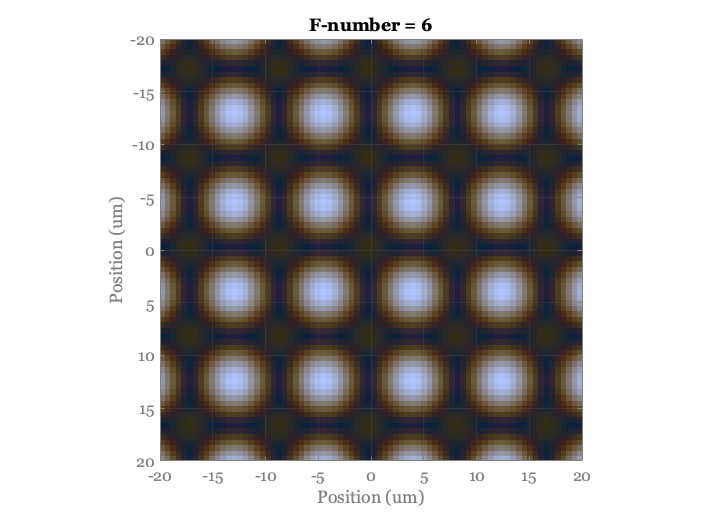


gridSpacing = 5;
oiPlot(oi2,'irradiance image with grid',[],gridSpacing);
set(gca,'xlim',[-20 20],'ylim',[-20 20])
title(sprintf('F-number = %.0f',fnBig))